# TÉCNICAS AVANZADAS DE GRÁFICOS

### Funciones de gráficos (Plot Functions)

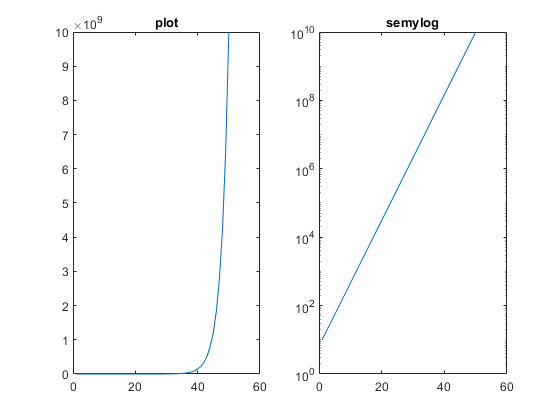

subplot(1, 2, 1)
plot(logspace(1, 10))
title("plot")
subplot(1, 2, 2)
semilogy(logspace(1, 10))
title("semylog")

% subplot para presentar tipos de plots
figure
year = 2013:2017

year =         2013        2014        2015        2016        2017


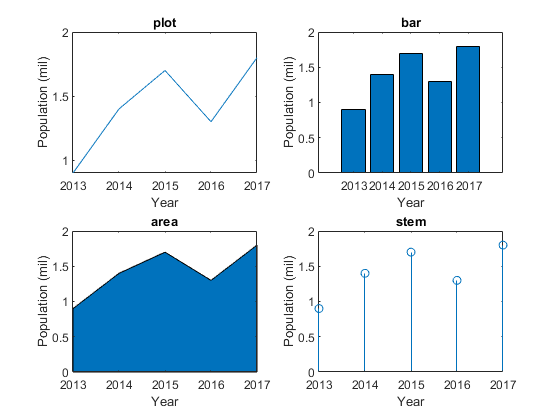

pop = [0.9 1.4 1.7 1.3 1.8];
subplot(2, 2, 1)
plot(year, pop)
title('plot')
xlabel('Year')
ylabel('Population (mil)')
subplot(2,2,2)
bar(year,pop)
title('bar')
xlabel('Year')
ylabel('Population (mil)')
subplot(2,2,3)
area(year,pop)
title('area')
xlabel('Year')
ylabel('Population (mil)')
subplot(2,2,4)
stem(year,pop)
title('stem')
xlabel('Year')
ylabel('Population (mil)')

% lo mismo pero con un loop
year = 2013:2017;
pop = [0.9 1.4 1.7 1.3 1.8];
titles = {'plot', 'bar', 'area', 'stem'};
for i = 1:4
    subplot(2,2,i)
    eval([titles{i} '(year,pop)'])
    title(titles{i})
    xlabel('Year')
    ylabel('Population (mil)')
end

Para una matri, las funciones de barra y de barra agruparán los valores en cada fila. 

figure
groupages = [8 19 43 25; 35 44 30 45]

groupages =      8    19    43    25
    35    44    30    45


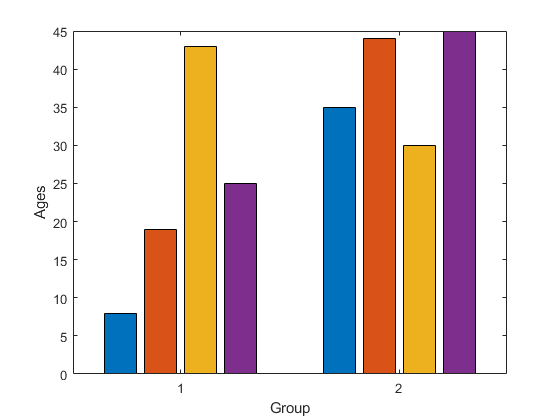

bar(groupages)
xlabel('Group')
ylabel('Ages')

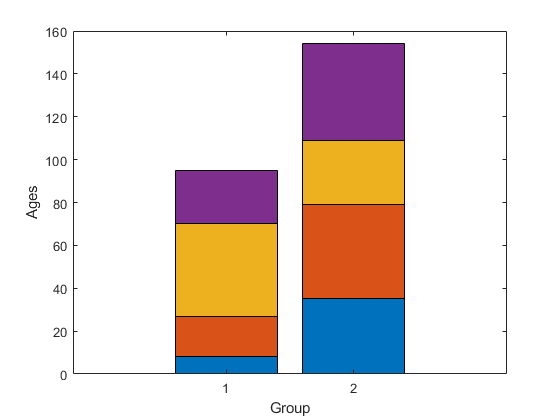

% los mismos datos pero con barras apiladas
figure
bar(groupages,'stacked')
xlabel('Group')
ylabel('Ages')

**Histograma**

Un histograma es un tipo particular de gráfico de barras que muestra la frecuencia de la aparición de valores dentro de un vector. Los histogramas usan lo que se llama "bins" para recoger valores que están en rangos dados. MATLAB tiene una función para crear un histograma, hist. Llamar a la función con la forma hist(vec) por defecto toma los valores en el vector vec y los pone en 10 contenedores (o hist(vec,n) pondrá en n contenedores.

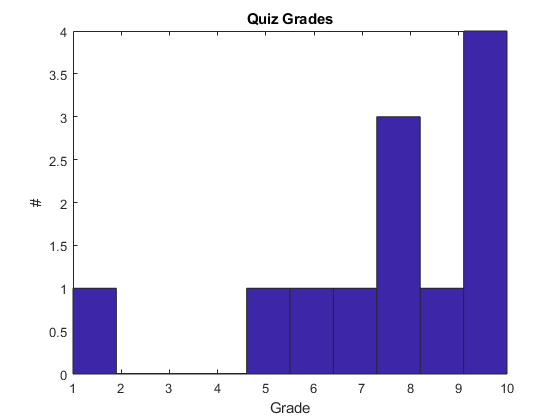

quizzes = [10 8 5 10 10 6 9 7 8 10 1 8];
hist(quizzes)
xlabel('Grade')
ylabel('#')
title('Quiz Grades')

La función de la hist también puede ser usada para devolver un vector que muestra cuántos de los valores del vector original caen en cada uno de los contenedores (bins).

c = hist(quizzes)

c =      1     0     0     0     1     1     1     3     1     4


**pie**

MATLAB tiene una función, pie (el pastel), que creará un gráfico circular. Llamar a la función con la forma pie(vec) dibuja un gráfico circular usando el porcentaje de cada elemento de vec de la totalidad (la suma). Muestra estos empezando desde la parte superior del círculo y dando vueltas en sentido contrario a las agujas del reloj. Por ejemplo, el primer valor en el vector 11 14 8 3 1, 11 es el 30% de la suma, 14 es el 38% de la suma, y así sucesivamente.

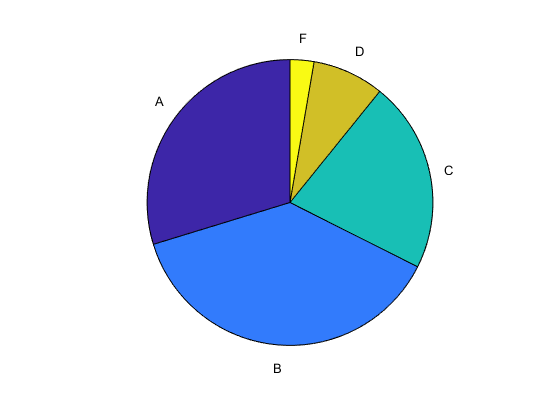

%pie([11 14 8 3 1])

% ahora con etiquetas
pie([11 14 8 3 1], {'A','B','C','D', 'F'})

### Trazados 3D

**plot3**

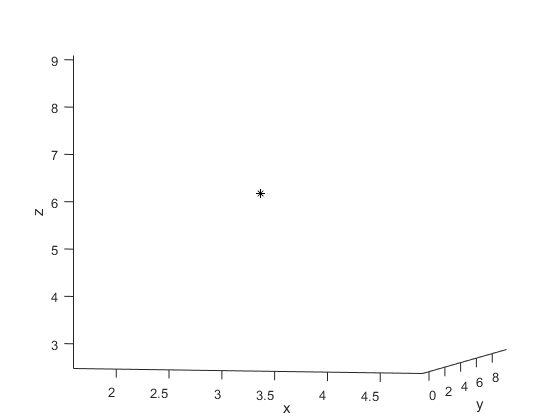

figure;
x = 1:5;
y = [0 -2 4 11 3];
z = 2:2:10;

plot3(x, y, z, 'k*')
xlabel('x')
ylabel('y')
zlabel('z')

title("3D Plot")

**bar3, bar3h**

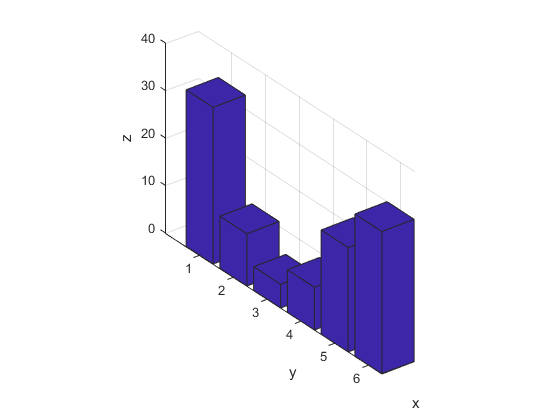

y = 1:6;
z = [33 11 5 9 22 30];
bar3(y, z)
xlabel("x")
ylabel("y")
zlabel("z")

mat = spiral(5)

mat =     21    22    23    24    25
    20     7     8     9    10
    19     6     1     2    11
    18     5     4     3    12
    17    16    15    14    13


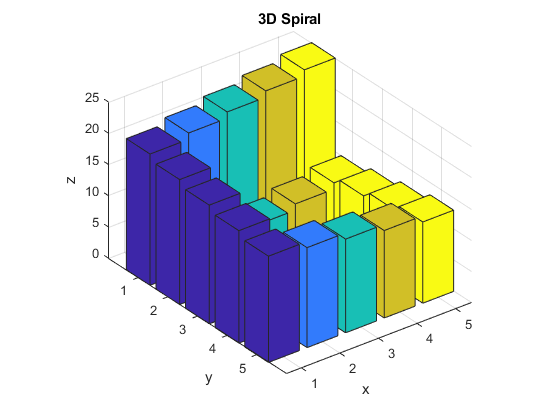

bar3(mat)
title("3D Spiral")
xlabel("x")
ylabel("y")
zlabel("z")

**pie3**

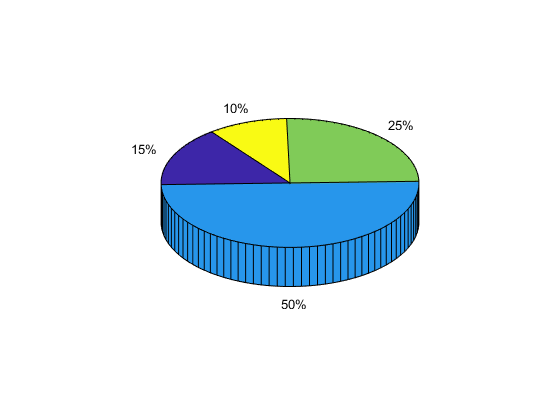

pie3([3 10 5 2])

**comet3**

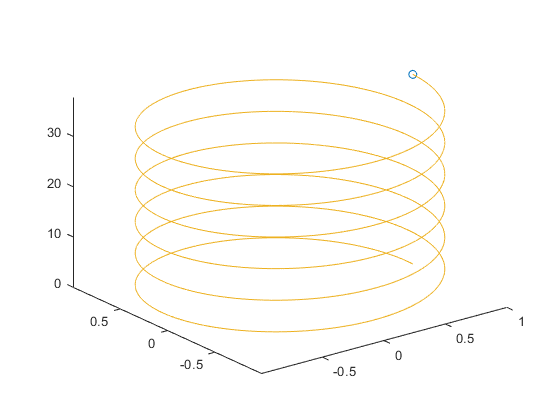

t = 0:0.001:12*pi;
comet3(cos(t), sin(t), t)

**mesh, surf**

Otros tipos de trama 3D interesantes incluyen mesh(malla) y el surf. La función de malla dibuja una malla de puntos 3D, mientras que la función de surf crea un gráfico de superficie usando el color para mostrar las superficies paramétricas deﬁnida por los puntos. MATLAB tiene varias funciones que crearán las matrices para las  coordenadas (x,y,z) para las formas específicas (por ejemplo, la esfera y el cilindro).

[x, y, z] = sphere(15);
size(x)

ans =     16    16


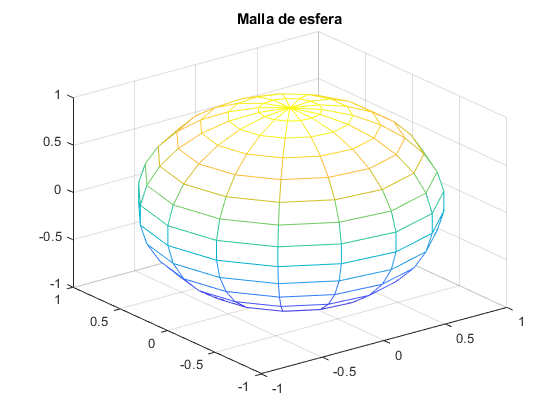

mesh(x, y, z)
title("Malla de esfera")

[x, y, z] = sphere(15)

x =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2079   -0.1899   -0.1391   -0.0642    0.0217    0.1040    0.1682    0.2034    0.2034    0.1682    0.1040    0.0217   -0.0642   -0.1391   -0.1899   -0.2079
   -0.4067   -0.3716   -0.2722   -0.1257    0.0425    0.2034    0.3291    0.3978    0.3978    0.3291    0.2034    0.0425   -0.1257   -0.2722   -0.3716   -0.4067
   -0.5878   -0.5370   -0.3933   -0.1816    0.0614    0.2939    0.4755    0.5749    0.5749    0.4755    0.2939    0.0614   -0.1816   -0.3933   -0.5370   -0.5878
   -0.7431   -0.6789   -0.4973   -0.2296    0.0777    0.3716    0.6012    0.7269    0.7269    0.6012    0.3716    0.0777   -0.2296   -0.4973   -0.6789   -0.7431
   -0.8660   -0.7912   -0.5795   -0.2676    0.0905    0.4330    0.7006    0.8471    0.8471    0.7006    0.4330    0.0905   -0.2676   -0.5795   -0.7912   -0.8660
   -0.9511   -0.8688   -0.6364

y =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -0.0846   -0.1545   -0.1977   -0.2068   -0.1801   -0.1222   -0.0432    0.0432    0.1222    0.1801    0.2068    0.1977    0.1545    0.0846         0
         0   -0.1654   -0.3023   -0.3868   -0.4045   -0.3522   -0.2391   -0.0846    0.0846    0.2391    0.3522    0.4045    0.3868    0.3023    0.1654         0
         0   -0.2391   -0.4368   -0.5590   -0.5846   -0.5090   -0.3455   -0.1222    0.1222    0.3455    0.5090    0.5846    0.5590    0.4368    0.2391         0
         0   -0.3023   -0.5523   -0.7068   -0.7391   -0.6436   -0.4368   -0.1545    0.1545    0.4368    0.6436    0.7391    0.7068    0.5523    0.3023         0
         0   -0.3522   -0.6436   -0.8236   -0.8613   -0.7500   -0.5090   -0.1801    0.1801    0.5090    0.7500    0.8613    0.8236    0.6436    0.3522         0
         0   -0.3868   -0.7068

z =    -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000
   -0.9781   -0.9781   -0.9781   -0.9781   -0.9781   -0.9781   -0.9781   -0.9781   -0.9781   -0.9781   -0.9781   -0.9781   -0.9781   -0.9781   -0.9781   -0.9781
   -0.9135   -0.9135   -0.9135   -0.9135   -0.9135   -0.9135   -0.9135   -0.9135   -0.9135   -0.9135   -0.9135   -0.9135   -0.9135   -0.9135   -0.9135   -0.9135
   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090
   -0.6691   -0.6691   -0.6691   -0.6691   -0.6691   -0.6691   -0.6691   -0.6691   -0.6691   -0.6691   -0.6691   -0.6691   -0.6691   -0.6691   -0.6691   -0.6691
   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000
   -0.3090   -0.3090   -0.3090

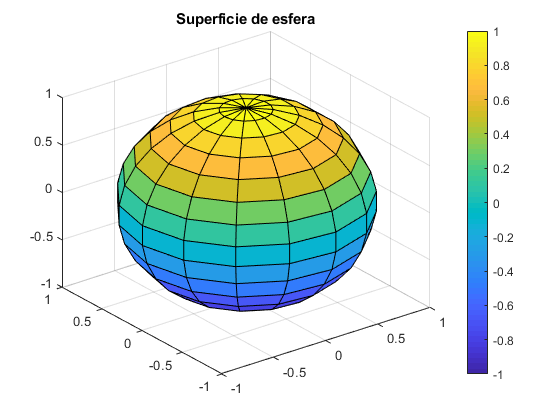

surf(x, y, z)
title('Superficie de esfera')
colorbar

La función de meshgrid puede ser usada para crear (x,y) puntos para los cuales z = f(x,y); entonces las matrices x, y, y z pueden pasar a la malla o al surf. Por ejemplo crea una gráfica de superficie de la función cos(x) + sin(y)

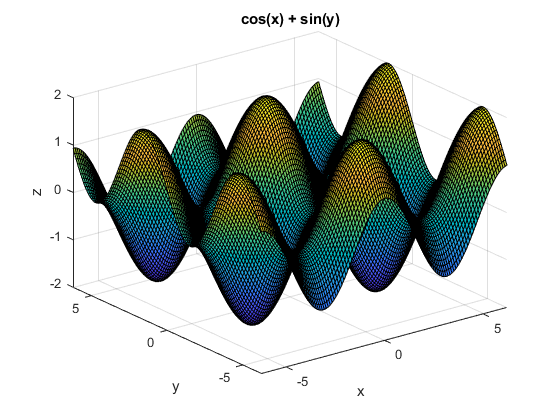

[x, y] = meshgrid(-2*pi: 0.1: 2*pi);
z = cos(x)+sin(y);
surf(x,y,z)
title('cos(x) + sin(y)')
xlabel('x')
ylabel('y')
zlabel('z')

### Personalizar gráficos

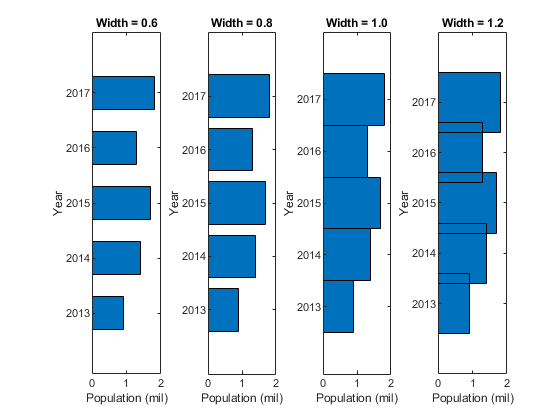

% Subplot to show varying bar widths
figure
year = 2013:2017;
pop = [0.9 1.4 1.7 1.3 1.8];
for i = 1:4
    subplot(1,4,i)
    % width will be 0.6, 0.8, 1, 1.2
    barh(year,pop,0.4+i*.2)
    title(sprintf('Width = %.1f',0.4+i*.2))
    xlabel('Population (mil)')
    ylabel('Year')
end

figure
gradenums = [11 14 8 3 1];
letgrades = {'A','B','C','D','F'};
which = gradenums == max(gradenums)

which = 1×5 logical array
   0   1   0   0   0


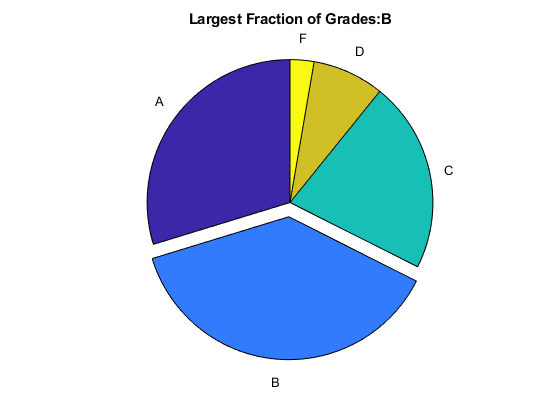

pie(gradenums,which,letgrades)
title(strcat('Largest Fraction of Grades: ', ...
letgrades(which)))

### Manejar gráficos y propiedades de gráficos

Organización de objetos gráficos

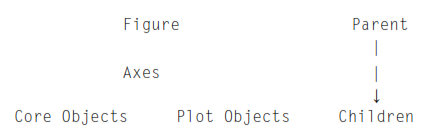

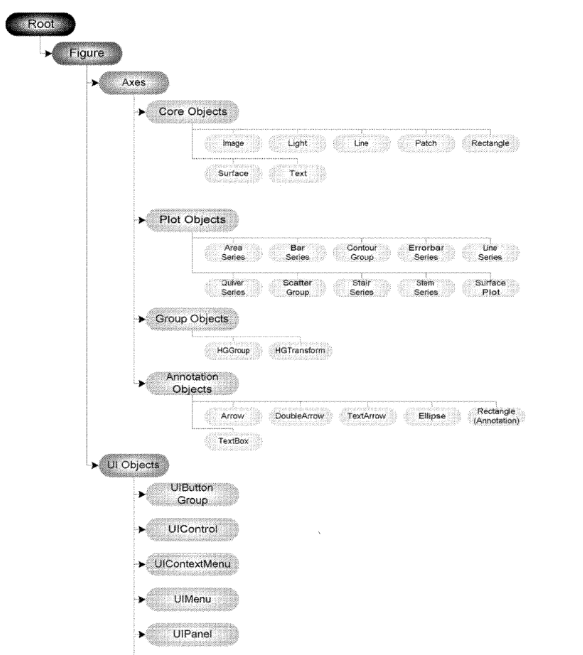

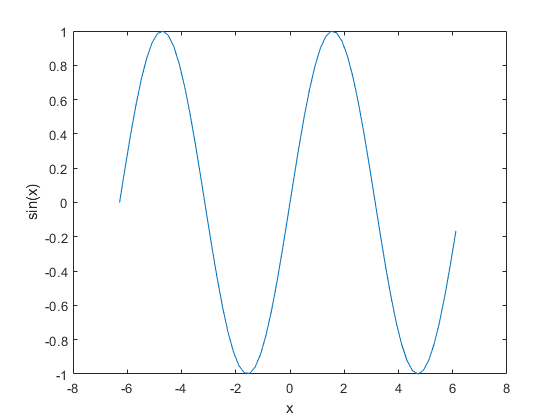

x = -2*pi:1/5:2*pi;
y = sin(x);
h1 = plot(x, y);
xlabel('x')
ylabel('sin(x)')

get(h1)

    AlignVertexCenters: 'off'
            Annotation: [1×1 matlab.graphics.eventdata.Annotation]
          BeingDeleted: 'off'
            BusyAction: 'queue'
         ButtonDownFcn: ''
              Children: [0×0 GraphicsPlaceholder]
              Clipping: 'on'
                 Color: [0 0.4470 0.7410]
             CreateFcn: ''
       DataTipTemplate: [1×1 matlab.graphics.datatip.DataTipTemplate]
             DeleteFcn: ''
           DisplayName: ''
      HandleVisibility: 'on'
               HitTest: 'on'
         Interruptible: 'on'
              LineJoin: 'round'
             LineStyle: '-'
             LineWidth: 0.5000
                Marker: 'none'
       MarkerEdgeColor: 'auto'
       MarkerFaceColor: 'none'
         MarkerIndices: [1×63 uint64]
            MarkerSize: 6
                Parent: [1×1 Axes]
         PickableParts: 'visible'
              Selected: 'off'
    SelectionHighlight: 'on'
                   Tag: ''
                  Type: 'line'
         UIContextMen

plotpro = get(h1)

plotpro = struct with fields:
                 Color: [0 0.4470 0.7410]
             LineStyle: '-'
             LineWidth: 0.5000
                Marker: 'none'
            MarkerSize: 6
       MarkerEdgeColor: 'auto'
       MarkerFaceColor: 'none'
              Clipping: 'on'
         MarkerIndices: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63]
    AlignVertexCenters: 'off'
              LineJoin: 'round'
              Children: [0×0 GraphicsPlaceholder]
                Parent: [1×1 Axes]
               Visible: 'on'
      HandleVisibility: 'on'
         UIContextMenu: [0×0 GraphicsPlaceholder]
         ButtonDownFcn: ''
            BusyAction: 'queue'
          BeingDeleted: 'off'
         Interruptible: 'on'
             CreateFcn: ''
             DeleteFcn: ''
                  Type: 'line'
                   Tag: ''
              UserData: []
   

plotpro.LineWidth()

ans = 0.5000

Color property

La propiedad de color es un vector el colo de las líneas como 3 valores separados para **Rojo, Verde **y** Azul. **Ejemplos:

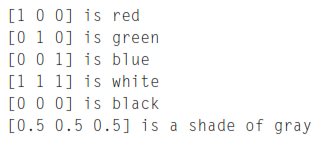

Todas las pripiedades por **get **pueden ser modificadas por la función set. La función set utiliza el formato.

%set(h1, 'LineWidth', 2.7)
% o
h1 = plot(x, y, 'LineWidth', 2.5)

h1 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 2.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×63 double]
              YData: [1×63 double]
              ZData: [1×0 double]

  Show all properties


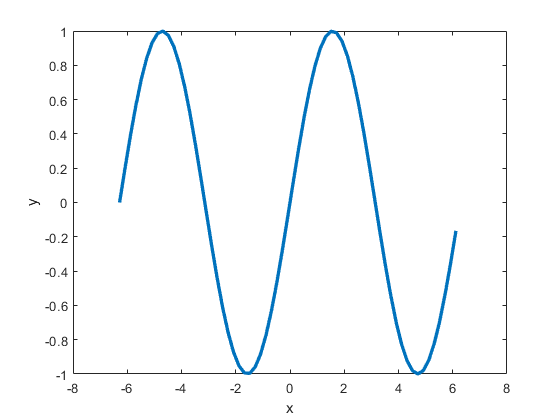

xlabel('x')
ylabel('y')

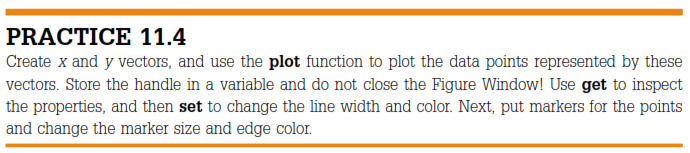

Objetos centrales

- line

- text

- rectangle

- patch

- image

Para ayuda utilizar **help line**

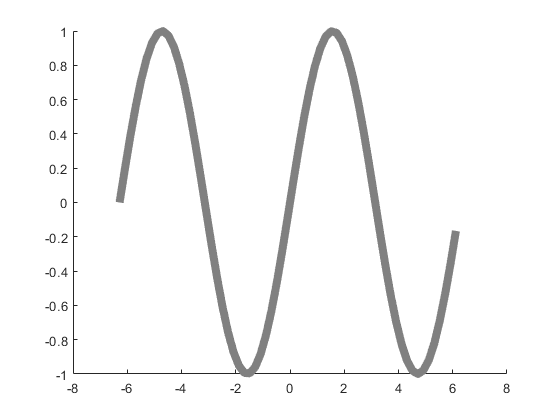

h1 =   Line with properties:

              Color: [0.5000 0.5000 0.5000]
          LineStyle: '-'
          LineWidth: 6
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×63 double]
              YData: [1×63 double]
              ZData: [1×0 double]

  Show all properties


figure
x = -2*pi:1/5:2*pi;
y = sin(x);
h1 = line(x, y, 'LineWidth', 6, 'Color', [0.5 0.5 0.5])

get(h1)

    AlignVertexCenters: 'off'
            Annotation: [1×1 matlab.graphics.eventdata.Annotation]
          BeingDeleted: 'off'
            BusyAction: 'queue'
         ButtonDownFcn: ''
              Children: [0×0 GraphicsPlaceholder]
              Clipping: 'on'
                 Color: [0.5000 0.5000 0.5000]
             CreateFcn: ''
             DeleteFcn: ''
           DisplayName: ''
      HandleVisibility: 'on'
               HitTest: 'on'
         Interruptible: 'on'
              LineJoin: 'round'
             LineStyle: '-'
             LineWidth: 6
                Marker: 'none'
       MarkerEdgeColor: 'auto'
       MarkerFaceColor: 'none'
         MarkerIndices: [1×63 uint64]
            MarkerSize: 6
                Parent: [1×1 Axes]
         PickableParts: 'visible'
              Selected: 'off'
    SelectionHighlight: 'on'
                   Tag: ''
                  Type: 'line'
         UIContextMenu: [0×0 GraphicsPlaceholder]
              UserData: []
              

**text**

figure
x = -4:0.2:4;
y = sin(x)

y =     0.7568    0.6119    0.4425    0.2555    0.0584   -0.1411   -0.3350   -0.5155   -0.6755   -0.8085   -0.9093   -0.9738   -0.9996   -0.9854   -0.9320   -0.8415   -0.7174   -0.5646   -0.3894   -0.1987         0    0.1987    0.3894    0.5646    0.7174    0.8415    0.9320    0.9854    0.9996    0.9738    0.9093    0.8085    0.6755    0.5155    0.3350    0.1411   -0.0584   -0.2555   -0.4425   -0.6119   -0.7568


hp = line(x, y, 'LineWidth', 3);
thand = text(2,0,'Sin(\pi)\rightarrow')

thand =   Text (Sin(\pi)\rightarrow) with properties:

                 String: 'Sin(\pi)\rightarrow'
               FontSize: 10
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0 0 0]
    HorizontalAlignment: 'left'
               Position: [2 0 0]
                  Units: 'data'

  Show all properties


get(thand)

        BackgroundColor: 'none'
           BeingDeleted: 'off'
             BusyAction: 'queue'
          ButtonDownFcn: ''
               Children: [0×0 GraphicsPlaceholder]
               Clipping: 'off'
                  Color: [0 0 0]
              CreateFcn: ''
              DeleteFcn: ''
              EdgeColor: 'none'
                Editing: 'off'
                 Extent: [2 -0.0525 0.9401 0.0991]
              FontAngle: 'normal'
               FontName: 'Helvetica'
               FontSize: 10
          FontSmoothing: 'on'
              FontUnits: 'points'
             FontWeight: 'normal'
       HandleVisibility: 'on'
                HitTest: 'on'
    HorizontalAlignment: 'left'
            Interpreter: 'tex'
          Interruptible: 'on'
              LineStyle: '-'
              LineWidth: 0.5000
                 Margin: 3
                 Parent: [1×1 Axes]
          PickableParts: 'visible'
               Position: [2 0 0]
               Rotation: 0
               Selecte

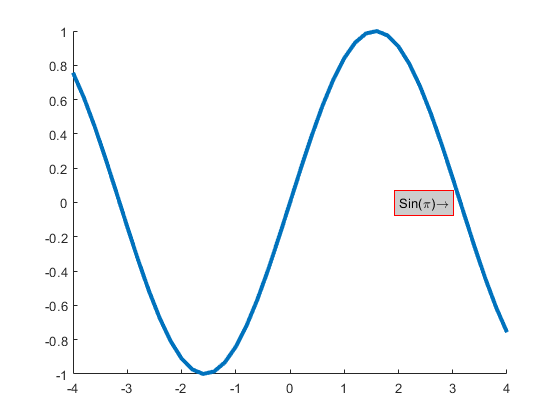

set(thand,'BackgroundColor',[0.8 0.8 0.8], ...
'EdgeColor',[1 0 0])

**rectangle**

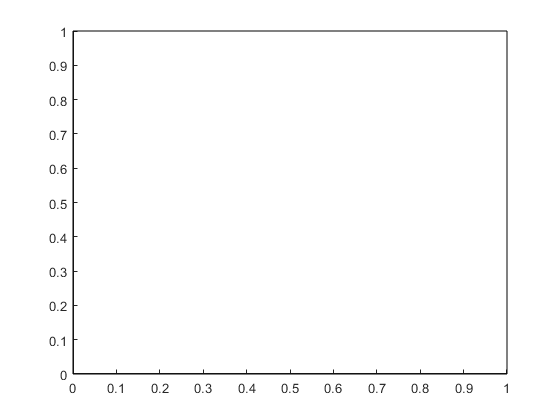

figure
recthand = rectangle;

get(recthand)

    AlignVertexCenters: 'off'
          BeingDeleted: 'off'
            BusyAction: 'queue'
         ButtonDownFcn: ''
              Children: [0×0 GraphicsPlaceholder]
              Clipping: 'on'
             CreateFcn: ''
             Curvature: [0 0]
             DeleteFcn: ''
             EdgeColor: [0 0 0]
             FaceColor: 'none'
      HandleVisibility: 'on'
               HitTest: 'on'
         Interruptible: 'on'
             LineStyle: '-'
             LineWidth: 0.5000
                Parent: [1×1 Axes]
         PickableParts: 'visible'
              Position: [0 0 1 1]
              Selected: 'off'
    SelectionHighlight: 'on'
                   Tag: ''
                  Type: 'rectangle'
         UIContextMenu: [0×0 GraphicsPlaceholder]
              UserData: []
               Visible: 'on'



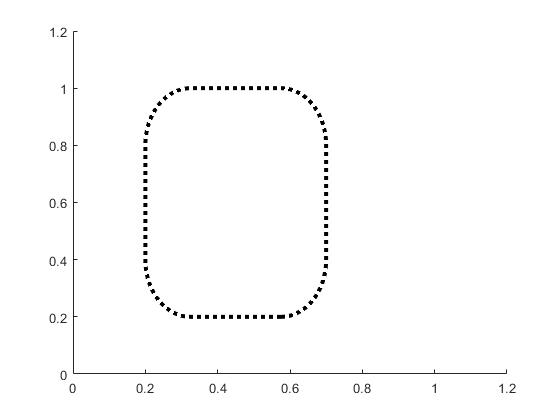

figure
rh = rectangle('Position', [0.2, 0.2, 0.5, 0.8], ...
    'Curvature', [0.5, 0.5]);
axis([0 1.2 0 1.2])
set(rh, 'Linewidth', 3, 'LineStyle', ':')

### Trazar aplicaciones

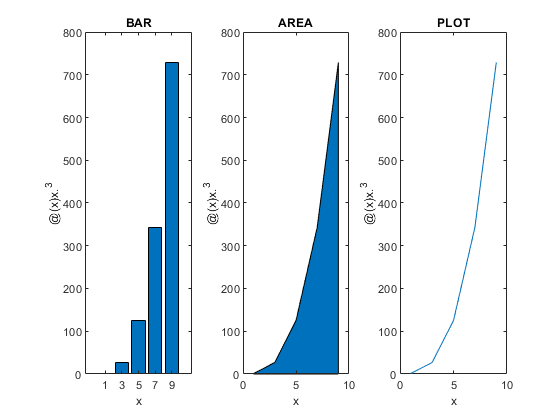

figure
anfn = @ (x) x .^ 3;
x = 1:2:9;
rca = {'bar', 'area', 'plot'};
plotxywithcell(x, anfn, rca)

### Guardar e imprimir gráficos

function plotxywithcell(x, fnhan, rca)
% plotxywithcell receives an x vector, the handle
% of a function (used to create a y vector), and
% a cell array with plot type names; it creates
% a subplot to show all of these plot types
% Format: plotxywithcell(x,fn handle, cell array)
lenrca = length(rca);
y = fnhan(x);
for i = 1:lenrca
    subplot(1,lenrca,i)
    funh = str2func(rca{i});
    funh(x,y)
    title(upper(rca{i}))
    xlabel('x')
    ylabel(func2str(fnhan))
end
end